# Сглаживающее среднее как цифровой фильтр

#### Формирование суммы двух синусоид разной частоты и амплитуды:

num = 5;
h = ones(1, num)./num;
t = 0:0.1:8;
x1 = cos(2*pi*0.5*t);
x2 = 0.25*cos(2*pi*5*t);
s = x1 + x2;
plot(t, s, 'LineWidth', 1);
hold on; grid on;

#### Свёртка сигнала с импульсной характеристикой:

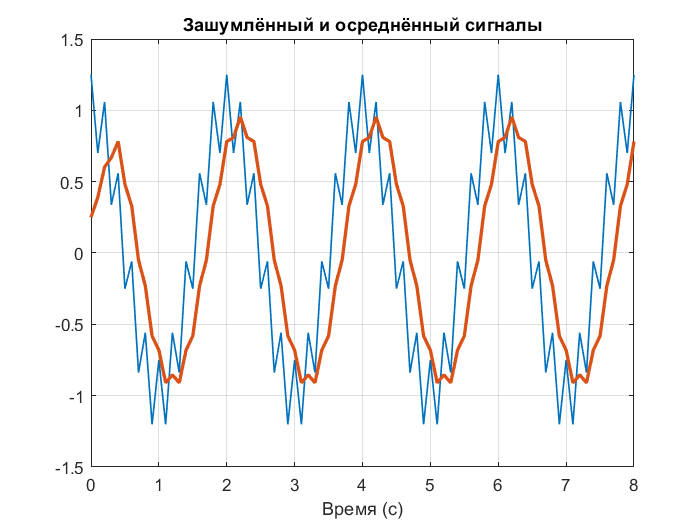

y = conv(s, h);
plot(t, y(1:length(t)), 'LineWidth', 2);
hold off;
title("Зашумлённый и осреднённый сигналы");
xlabel('Время (с)');

#### Оценка АЧХ и ФЧХ фильтра:

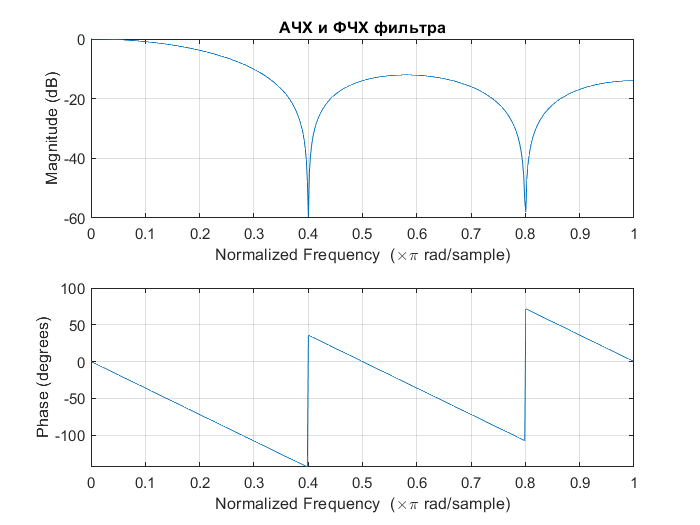

freqz(h, 1);
title("АЧХ и ФЧХ фильтра");